# Test Case - Power Split Drive Unit

mdl = "PowerSplitDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
PowerSplitDriveUnit_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Road grade", Time="2");
simIn = setBlockParameter(simIn, mdl+"/Road grade", After="0");

simIn = setBlockParameter(simIn, mdl+"/Brake force", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Brake force", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Brake force", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", Before="163");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", After="163");

simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", After="0");

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Before="145");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", After="145");

% Initial conditions

simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

simIn = setVariable(simIn, "initial.engine_speed_rpm", 2000);

simIn = setVariable(simIn, "initial.MG1_Temperature_degC", 20);
simIn = setVariable(simIn, "initial.MG1_AirTemp_degC", 20);

simIn = setVariable(simIn, "initial.MG2_Temperature_degC", 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_degC", 20);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "15");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

## Visualize Simulation Result

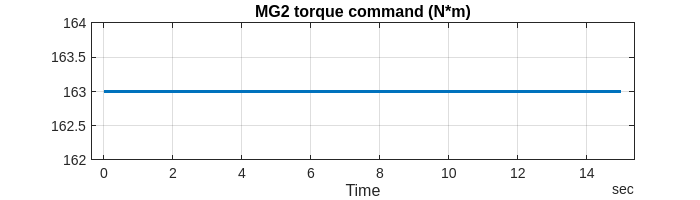

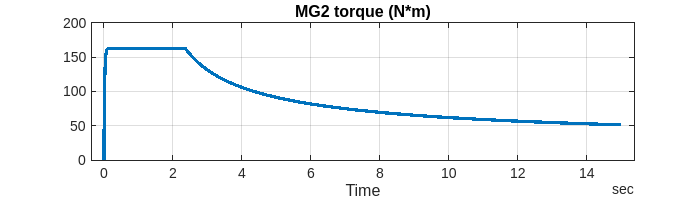

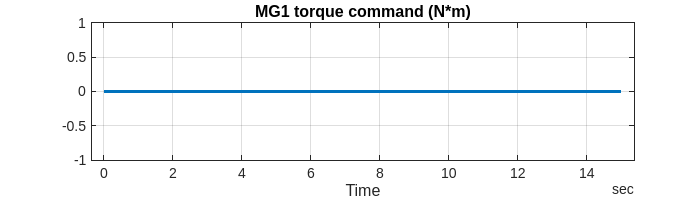

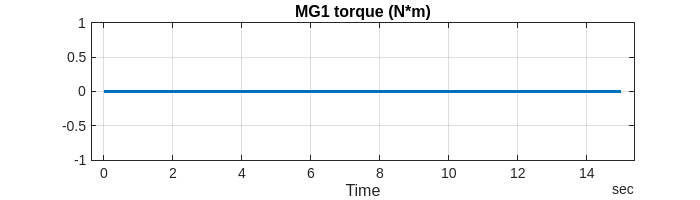

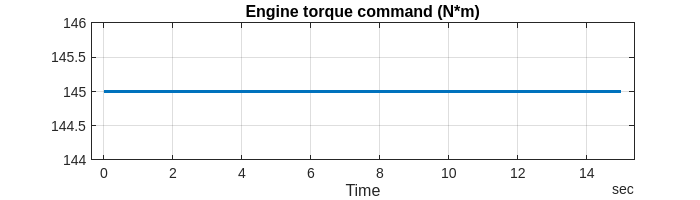

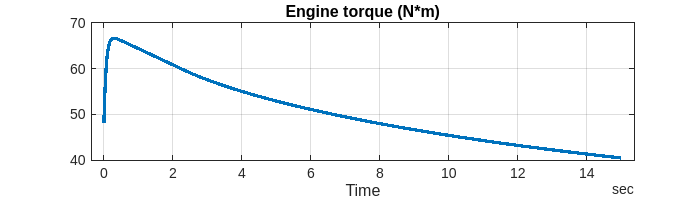

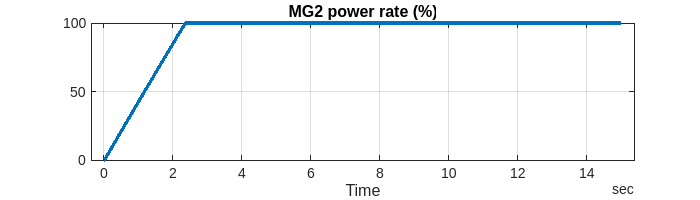

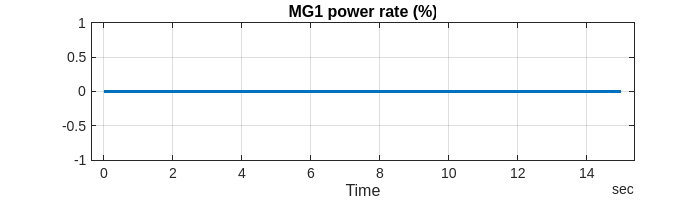

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "MG2 torque command", ...
  "MG2 torque", ...
  "MG1 torque command", ...
  "MG1 torque", ...
  "Engine torque command", ...
  "Engine torque", ...
  "MG2 power rate", ...
  "MG1 power rate", ...
  "MG2 speed", ...
  "MG1 speed", ...
  "Engine speed", ...
  "Vehicle speed kph", ...
  "Vehicle speed mph", ...
  "G force", ...
  "Battery SOC" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 200;
end

*Copyright 2021-2022 The Mathworks, Inc.*